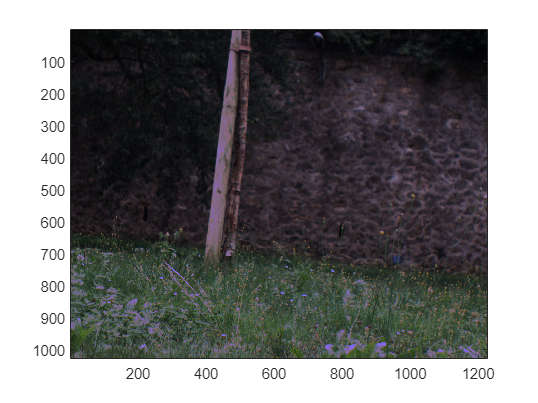

% Load and initialize images
arbres = imread("arbre.png");
routes = imread("route.png");
arbre = double(arbres);
route = double(routes);

% Parameters
f = 25*1e-3;
x_0 = -2;
t_pix = 5e-6;
N = 2.8;
x = linspace(-5,-1,1000);
f_R = 25.1e-3;
f_V = 25e-3;
f_B = 24.8e-3;

% Image visualization
figure(1)
imagesc(arbres)

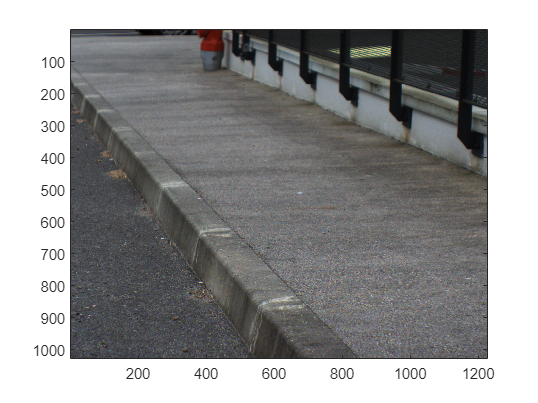


figure(2)
imagesc(routes)

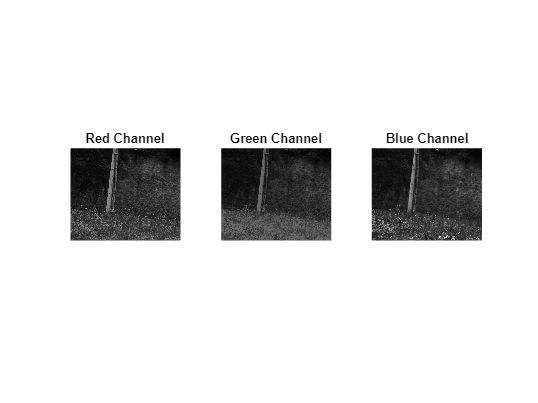


% RGB channel visualization
[R,G,B] = imsplit(arbres);
[R_2,G_2,B_2] = imsplit(routes);

figure(3)
subplot(1,3,1)
imshow(R)
title('Red Channel')
subplot(1,3,2)
imshow(G)
title('Green Channel')
subplot(1,3,3)
imshow(B)
title('Blue Channel')

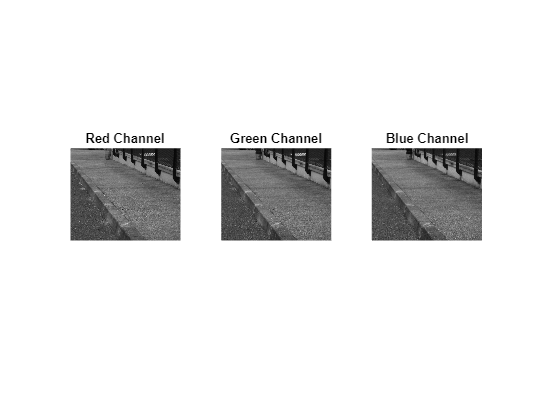


figure(4)
subplot(1,3,1)
imshow(R_2)
title('Red Channel')
subplot(1,3,2)
imshow(G_2)
title('Green Channel')
subplot(1,3,3)
imshow(B_2)
title('Blue Channel')

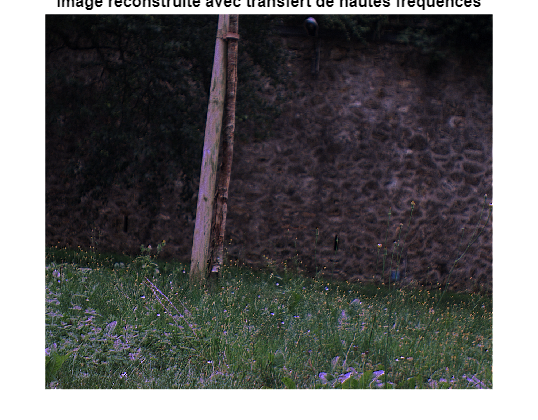


% Gradient calculation
R_d = double(R);
G_d = double(G);
B_d = double(B);
R_2d = double(R_2);
G_2d = double(G_2);
B_2d = double(B_2);

[gx_R,gy_R] = gradient(R_d);
[gx_G,gy_G] = gradient(G_d);
[gx_B,gy_B] = gradient(B_d);
[gx_R2,gy_R2] = gradient(R_2d);
[gx_G2,gy_G2] = gradient(G_2d);
[gx_B2,gy_B2] = gradient(B_2d);

g_R = sqrt(gx_R.^2+gy_R.^2);
g_G = sqrt(gx_G.^2+gy_G.^2);
g_B = sqrt(gx_B.^2+gy_B.^2);
g_R2 = sqrt(gx_R2.^2+gy_R2.^2);
g_G2 = sqrt(gx_G2.^2+gy_G2.^2);
g_B2 = sqrt(gx_B2.^2+gy_B2.^2);

% Filtering
Filtre = ones(10,10);
g_R_f = conv2(g_R,Filtre,'same');
g_G_f = conv2(g_G,Filtre,'same');
g_B_f = conv2(g_B,Filtre,'same');

% Transfer coefficient calculation
alpha = g_R_f.^2./(g_R_f.^2+g_G_f.^2+g_B_f.^2);
beta = g_G_f.^2./(g_R_f.^2+g_G_f.^2+g_B_f.^2);
gamma = g_B_f.^2./(g_R_f.^2+g_G_f.^2+g_B_f.^2);

% Convertir arbre en double avant le traitement
arbre = double(arbres);

% Extraire les canaux
[R_d, G_d, B_d] = imsplit(arbre);
R_d = double(R_d);
G_d = double(G_d);
B_d = double(B_d);

% High frequency transfer
[xSize, ySize] = size(R_d);
sigma = 0.3;
[X, Y] = meshgrid(1:xSize, 1:ySize);
mu_x = xSize/2;
mu_y = ySize/2;
gaussienne = exp(-((X - mu_x).^2 + (Y - mu_y).^2)/(2*sigma^2));

HFR = R_d-conv2(R_d,gaussienne,'same');
HFG = G_d-conv2(G_d,gaussienne,'same');
HFB = B_d-conv2(B_d,gaussienne,'same');

% Reconstruire chaque canal séparément
y_f_R = R_d + alpha.*HFR + beta.*HFG + gamma.*HFB;
y_f_G = G_d + alpha.*HFR + beta.*HFG + gamma.*HFB; 
y_f_B = B_d + alpha.*HFR + beta.*HFG + gamma.*HFB;

% Combiner les canaux et clipper
y_f = cat(3, y_f_R, y_f_G, y_f_B);
y_f_clip = uint8(max(0, min(255, y_f)));

figure(5)
imshow(y_f_clip)
title('Image reconstruite avec transfert de hautes fréquences')


% Image position calculation
x1 = (x_0*f)/(x_0+f);

% Depth of field analysis
epsilon_R = (f^2)/(N*t_pix).*(1/f_R+1./x-1/x1);
epsilon_G = (f^2)/(N*t_pix).*(1/f_V+1./x-1/x1);
epsilon_B = (f^2)/(N*t_pix).*(1/f_B+1./x-1/x1);

net_R = abs(epsilon_R) <= 1;
net_G = abs(epsilon_G) <= 1;
net_B = abs(epsilon_B) <= 1;

zone_nette = net_R | net_G | net_B;
GDOF = sum(zone_nette) * (x(2)-x(1));
fprintf('GDOF totale : %.2f m\n', GDOF);

GDOF totale : 0.64 m


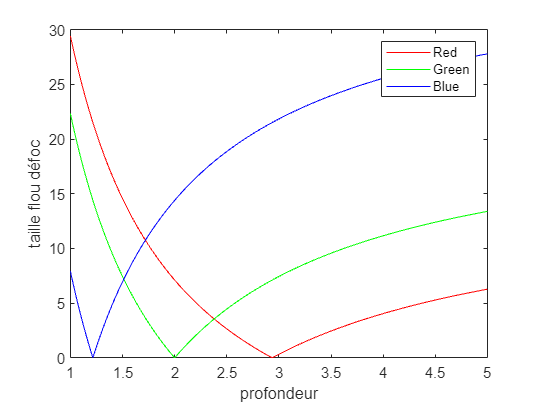


figure(7)
plot(abs(x),abs(epsilon_R),'r')
hold on
plot(abs(x),abs(epsilon_G),'g')
plot(abs(x),abs(epsilon_B),'b')
xlabel('profondeur')
ylabel('taille flou défoc')
legend('Red','Green','Blue')

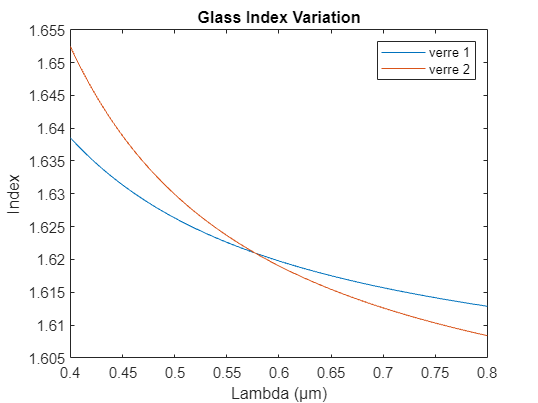


% Index variation analysis
lambda_visible = linspace(0.4,0.8,1000);
n = zeros(length(lambda_visible),2);
for i = 1:length(lambda_visible)
    n(i,:) = index_addon(lambda_visible(i));
end

figure(10)
plot(lambda_visible,n(:,1))
hold on
plot(lambda_visible,n(:,2))
xlabel('Lambda (µm)')
ylabel('Index')
title('Glass Index Variation')
legend('verre 1','verre 2')

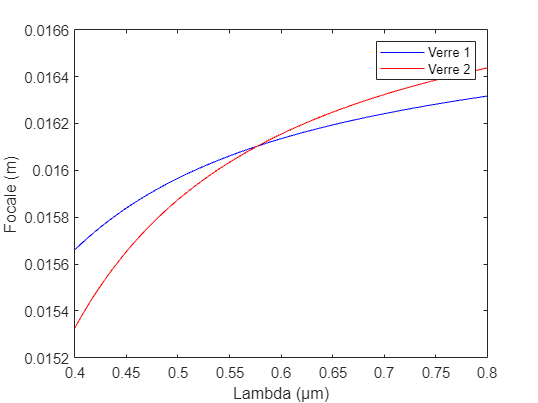


% Focal length calculation
R = 0.01;
[focales1, focales2] = calcul_focale(R, lambda_visible);

figure(11)
plot(lambda_visible, focales1, 'b', lambda_visible, focales2, 'r')
xlabel('Lambda (µm)')
ylabel('Focale (m)')
legend('Verre 1', 'Verre 2')

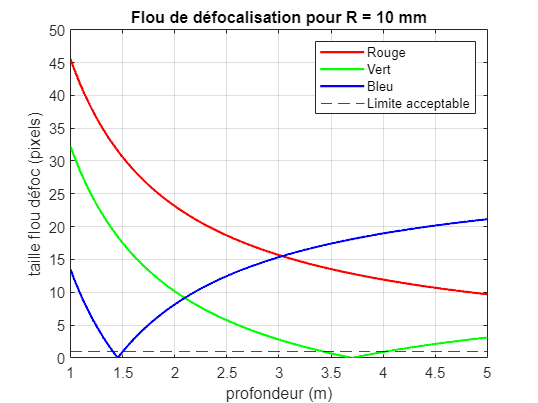


[a,b,c]=Pdf(f,N,t_pix,x1,x);

plot_flou_defoc(x,R)

optimize_gdof(x)

R optimal = 0.010 m
GDOF maximale = 1.001 m


ans = 0.0100

optimize_gdof_x0(x)

R optimal = 0.060 m
x0 optimal = -3.694 m
GDOF maximale = 1.922 m


ans = 0.0600

function [taille_flou,limite_proche,limite_loin] = Pdf(f,N,t_pix,x1,x)
    epsilon = (f^2)/(N*t_pix).*(1/f+1./x-1/x1);
    masque_net = abs(epsilon)<=1;
    indices_net = find(masque_net);
    limite_proche = x(indices_net(1));
    limite_loin = x(indices_net(end));
    taille_flou = limite_loin-limite_proche;
end


%% Supporting Functions
function [arbres, routes] = loadImages(arbre_path, route_path)
    arbres = imread(arbre_path);
    routes = imread(route_path);
end

function [R, G, B] = preprocessImages(img)
    [R, G, B] = imsplit(img);
    R = double(R);
    G = double(G);
    B = double(B);
end

function [gx, gy, g] = computeGradients(channel)
    [gx, gy] = gradient(channel);
    g = sqrt(gx.^2 + gy.^2);
end

function [g_R_f, g_G_f, g_B_f] = applyGradientFiltering(g_R, g_G, g_B, filter_size)
    filter = ones(filter_size);
    g_R_f = conv2(g_R, filter, 'same');
    g_G_f = conv2(g_G, filter, 'same');
    g_B_f = conv2(g_B, filter, 'same');
end

function [alpha, beta, gamma] = computeTransferCoefficients(g_R, g_G, g_B)
    denominator = g_R.^2 + g_G.^2 + g_B.^2;
    alpha = g_R.^2 ./ denominator;
    beta = g_G.^2 ./ denominator;
    gamma = g_B.^2 ./ denominator;
end

function x_prime = computeImageDistance(x_0, f)
    x_prime = (x_0 * f) / (x_0 + f);
end

function epsilon = computeDefocusBlur(f, N, t_pix, x_prime_0, x)
    epsilon = (f^2) / (N * t_pix) .* (1/f + 1./x - 1/x_prime_0);
end

function plotDefocusCurves(params)
    figure('Name', 'Defocus Curves');
    x_prime_0 = computeImageDistance(params.x_0, params.f_V);
    
    % Calculate epsilon for each channel
    eps_R = computeDefocusBlur(params.f_R, params.N, params.t_pix, x_prime_0, params.depth_range);
    eps_V = computeDefocusBlur(params.f_V, params.N, params.t_pix, x_prime_0, params.depth_range);
    eps_B = computeDefocusBlur(params.f_B, params.N, params.t_pix, x_prime_0, params.depth_range);
    
    plot(abs(params.depth_range), abs(eps_R), 'r', 'LineWidth', 2);
    hold on;
    plot(abs(params.depth_range), abs(eps_V), 'g', 'LineWidth', 2);
    plot(abs(params.depth_range), abs(eps_B), 'b', 'LineWidth', 2);
    yline(1, 'k--', 'LineWidth', 1.5);
    
    xlabel('Depth (m)');
    ylabel('Defocus Blur Size (pixels)');
    title('RGB Channel Defocus Curves');
    legend('Red', 'Green', 'Blue', 'Acceptable Blur Limit');
    grid on;
end

function gdof = computeGeneralizedDOF(params)
    x_prime_0 = computeImageDistance(params.x_0, params.f_V);
    
    % Calculate DoF for each channel
    dof_R = calculateChannelDOF(params.f_R, params.N, params.t_pix, x_prime_0, params.depth_range);
    dof_V = calculateChannelDOF(params.f_V, params.N, params.t_pix, x_prime_0, params.depth_range);
    dof_B = calculateChannelDOF(params.f_B, params.N, params.t_pix, x_prime_0, params.depth_range);
    
    % Compute union of DOFs
    combined_dof = unique([dof_R; dof_V; dof_B]);
    gdof = max(combined_dof) - min(combined_dof);
end

function dof = calculateChannelDOF(f, N, t_pix, x_prime_0, depth_range)
    epsilon = computeDefocusBlur(f, N, t_pix, x_prime_0, depth_range);
    in_dof = abs(epsilon) <= 1;
    dof = depth_range(in_dof);
end

function [R_opt, x0_opt] = optimizeParameters(params)
    % Define optimization ranges
    R_range = linspace(0.01, 0.05, 50);  % 10-50mm range
    x0_range = linspace(-3, -1, 50);     % 1-3m range
    
    max_gdof = 0;
    R_opt = R_range(1);
    x0_opt = x0_range(1);
    
    % Grid search optimization
    for R = R_range
        for x0 = x0_range
            % Update parameters
            test_params = params;
            [test_params.f_R, test_params.f_V, test_params.f_B] = calculateFocals(R);
            test_params.x_0 = x0;
            
            % Calculate GDOF
            gdof = computeGeneralizedDOF(test_params);
            
            % Update if better
            if gdof > max_gdof
                max_gdof = gdof;
                R_opt = R;
                x0_opt = x0;
            end
        end
    end
end

function [f1, f2] = calcul_focale(R, lambda)
    % Préallocation
    f1 = zeros(1, length(lambda));
    f2 = zeros(1, length(lambda));
    
    % Calcul pour chaque longueur d'onde
    for i = 1:length(lambda)
        n = index_addon(lambda(i));
        f1(i) = R/(n(1)-1);
        f2(i) = R/(n(2)-1);
    end
end

function plot_flou_defoc(x, R)
   % Calcul des focales
   lambda_R = 0.605;
   lambda_G = 0.530; 
   lambda_B = 0.465;
   
   % Calcul des indices pour chaque longueur d'onde
   n_R = index_addon(lambda_R);
   n_G = index_addon(lambda_G);
   n_B = index_addon(lambda_B);
   
   % Calcul des focales totales
   f_total_R = 1/((n_R(2)-n_R(1))/R + 1/0.025);
   f_total_G = 1/((n_G(2)-n_G(1))/R + 1/0.025);
   f_total_B = 1/((n_B(2)-n_B(1))/R + 1/0.025);
   
   % Paramètres
   N = 2.8;
   t_pix = 5e-6;
   x_0 = -3.7;
   x1 = (x_0*f_total_G)/(x_0+f_total_G);
   
   % Calcul du flou de défocalisation
   epsilon_R = (f_total_R^2)/(N*t_pix).*(1/f_total_R+1./x-1/x1);
   epsilon_G = (f_total_G^2)/(N*t_pix).*(1/f_total_G+1./x-1/x1);
   epsilon_B = (f_total_B^2)/(N*t_pix).*(1/f_total_B+1./x-1/x1);
   
   % Affichage
   figure
   plot(abs(x), abs(epsilon_R), 'r', 'LineWidth', 1.5)
   hold on
   plot(abs(x), abs(epsilon_G), 'g', 'LineWidth', 1.5)
   plot(abs(x), abs(epsilon_B), 'b', 'LineWidth', 1.5)
   yline(1, 'k--')
   xlabel('profondeur (m)')
   ylabel('taille flou défoc (pixels)')
   title('Flou de défocalisation pour R = ' + string(R*1000) + ' mm')
   legend('Rouge', 'Vert', 'Bleu', 'Limite acceptable')
   grid on
end

function R_optimal = optimize_gdof(x)
   R_range = linspace(0.005, 0.5, 100);
   max_gdof = 0;
   R_optimal = R_range(1);
   
   for R_test = R_range
       lambda_R = 0.605; lambda_G = 0.530; lambda_B = 0.465;
       n_R = index_addon(lambda_R);
       n_G = index_addon(lambda_G);
       n_B = index_addon(lambda_B);
       
       f_total_R = 1/((n_R(2)-n_R(1))/R_test + 1/0.025);
       f_total_G = 1/((n_G(2)-n_G(1))/R_test + 1/0.025);
       f_total_B = 1/((n_B(2)-n_B(1))/R_test + 1/0.025);
       
       N = 2.8;
       t_pix = 5e-6;
       x_0 = -2;
       x1 = (x_0*f_total_G)/(x_0+f_total_G);
       
       epsilon_R = (f_total_R^2)/(N*t_pix).*(1/f_total_R+1./x-1/x1);
       epsilon_G = (f_total_G^2)/(N*t_pix).*(1/f_total_G+1./x-1/x1);
       epsilon_B = (f_total_B^2)/(N*t_pix).*(1/f_total_B+1./x-1/x1);
       
       net_R = abs(epsilon_R) <= 1;
       net_G = abs(epsilon_G) <= 1;
       net_B = abs(epsilon_B) <= 1;
       
       gdof = sum(net_R | net_G | net_B) * (x(2)-x(1));
       
       if gdof > max_gdof
           max_gdof = gdof;
           R_optimal = R_test;
       end
   end
   
   fprintf('R optimal = %.3f m\n', R_optimal);
   fprintf('GDOF maximale = %.3f m\n', max_gdof);
end
function [R_optimal, x0_optimal, gdof_max] = optimize_gdof_x0(x)
   R_range = linspace(0.01, 0.5, 50);
   x0_range = linspace(-5, -1, 50);
   gdof_max = 0;
   
   for R = R_range
       for x0 = x0_range
           lambda_R = 0.605; lambda_G = 0.530; lambda_B = 0.465;
           n_R = index_addon(lambda_R);
           n_G = index_addon(lambda_G);
           n_B = index_addon(lambda_B);
           
           f_total_R = 1/((n_R(2)-n_R(1))/R + 1/0.025);
           f_total_G = 1/((n_G(2)-n_G(1))/R + 1/0.025);
           f_total_B = 1/((n_B(2)-n_B(1))/R + 1/0.025);
           
           N = 2.8;
           t_pix = 5e-6;
           x1 = (x0*f_total_G)/(x0+f_total_G);
           
           epsilon_R = (f_total_R^2)/(N*t_pix).*(1/f_total_R+1./x-1/x1);
           epsilon_G = (f_total_G^2)/(N*t_pix).*(1/f_total_G+1./x-1/x1);
           epsilon_B = (f_total_B^2)/(N*t_pix).*(1/f_total_B+1./x-1/x1);
           
           net_R = abs(epsilon_R) <= 1;
           net_G = abs(epsilon_G) <= 1;
           net_B = abs(epsilon_B) <= 1;
           
           gdof = sum(net_R | net_G | net_B) * (x(2)-x(1));
           
           if gdof > gdof_max
               gdof_max = gdof;
               R_optimal = R;
               x0_optimal = x0;
           end
       end
   end
   
   fprintf('R optimal = %.3f m\n', R_optimal);
   fprintf('x0 optimal = %.3f m\n', x0_optimal);
   fprintf('GDOF maximale = %.3f m\n', gdof_max);
end